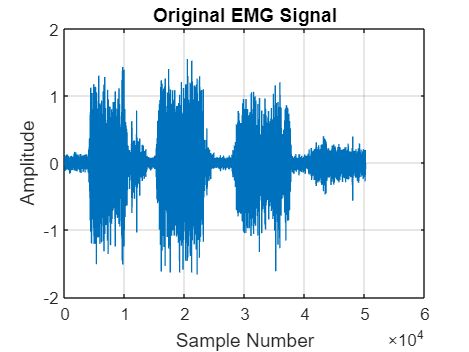

% Load the EMG signal from the .mat file
emg_signal=load("F:\IITM\Physiological measurements lab\EMG data\KaviNonDom.mat"); % Replace 'your_emg_data.mat' with the actual filename
my_data=emg_signal.data;
% Plot the original EMG signal
figure;
plot(my_data);
title('Original EMG Signal');
xlabel('Sample Number');
ylabel('Amplitude');
grid on;

%separating the peaks based on activity for grip strength
force_max=my_data(14447:25525);%maximum grip stength
force_50=my_data(26288:38978);%50% of maximum grip strength
force_10=my_data(39000:50000);%10% of maximum grip strength
%for maximum grip strength
%RMS Vaue
rms_value_max = rms(force_max);
disp(['RMS Value for maximum grip strength for dominant hand: ', num2str(rms_value_max)]);

RMS Value for maximum grip strength for dominant hand: 0.36058


%Mean absolute value
mav_value_max = mean(abs(force_max));
disp(['Mean Absolute Value (MAV) for maximum grip strength for dominant hand: ', num2str(mav_value_max)]);

Mean Absolute Value (MAV) for maximum grip strength for dominant hand: 0.24292


%Max amplitude
max_amplitude_max = max(abs(force_max));
disp(['Maximum Amplitude for maximum grip strength for dominant hand: ', num2str(max_amplitude_max)]);

Maximum Amplitude for maximum grip strength for dominant hand: 1.6641


%Zero crossing rate
zero_crossings_max = sum(abs(diff(sign(force_max))) > 0);
zero_crossing_rate_max = zero_crossings_max / (length(force_max) - 1);
disp(['Zero-Crossing Rate for maximum grip strength for dominant hand:: ', num2str(zero_crossing_rate_max)]);

Zero-Crossing Rate for maximum grip strength for dominant hand:: 0.14091


%for 50 % of Maximum grip strength
 
%RMS Vaue
rms_value_50= rms(force_50);
disp(['RMS Value for 50 % of maximum grip strength for dominant hand: ', num2str(rms_value_50)]);

RMS Value for 50 % of maximum grip strength for dominant hand: 0.25489


%Mean absolute value
mav_value_50= mean(abs(force_50));
disp(['Mean Absolute Value (MAV) for 50 % of maximum grip strength for dominant hand: ', num2str(mav_value_50)]);

Mean Absolute Value (MAV) for 50 % of maximum grip strength for dominant hand: 0.16944


%Max amplitude
max_amplitude_50 = max(abs(force_50));
disp(['Maximum Amplitude for 50 % of maximum grip strength for dominant hand: ', num2str(max_amplitude_50)]);

Maximum Amplitude for 50 % of maximum grip strength for dominant hand: 1.6159


%Zero crossing rate
zero_crossings_50 = sum(abs(diff(sign(force_50))) > 0);
zero_crossing_rate_50 = zero_crossings_50 / (length(force_50) - 1);
disp(['Zero-Crossing Rate for 50 % of maximum grip strength for dominant hand:: ', num2str(zero_crossing_rate_50)]);

Zero-Crossing Rate for 50 % of maximum grip strength for dominant hand:: 0.13507


%for 10 % of Maximum grip strength
%RMS Vaue
rms_value_10= rms(force_10);
disp(['RMS Value for 10 % of maximum grip strength for dominant hand: ', num2str(rms_value_10)]);

RMS Value for 10 % of maximum grip strength for dominant hand: 0.084501


%Mean absolute value
mav_value_10= mean(abs(force_10));
disp(['Mean Absolute Value (MAV) for 10 % of maximum grip strength for dominant hand: ', num2str(mav_value_10)]);

Mean Absolute Value (MAV) for 10 % of maximum grip strength for dominant hand: 0.061312


%Max amplitude
max_amplitude_10 = max(abs(force_10));
disp(['Maximum Amplitude for 10 % of maximum grip strength for dominant hand: ', num2str(max_amplitude_10)]);

Maximum Amplitude for 10 % of maximum grip strength for dominant hand: 0.56732


%Zero crossing rate
zero_crossings_10 = sum(abs(diff(sign(force_10))) > 0);
zero_crossing_rate_10 = zero_crossings_10 / (length(force_10) - 1);
disp(['Zero-Crossing Rate for 10 % of maximum grip strength for dominant hand:: ', num2str(zero_crossing_rate_10)]);

Zero-Crossing Rate for 10 % of maximum grip strength for dominant hand:: 0.13909


% Sample EMG signal and time vector (replace with your actual data)
fs = 1000; % Sampling frequency in Hz
% Calculate the RMS of the EMG signal in a sliding manner
windowSize = 100; % Choose an appropriate window size
rmsValues_max = zeros(1, length(force_max) - windowSize + 1);
 
for i = 1:length(rmsValues_max)
    rmsValues_max(i) = rms(force_max(i:i+windowSize-1));
end


% Create a time vector for RMS values
timeRMS_max = (0:length(rmsValues_max)-1) / fs;
 
%for 50% force 
rmsValues_50 = zeros(1, length(force_50) - windowSize + 1);
 
for i = 1:length(rmsValues_50)
    rmsValues_50(i) = rms(force_50(i:i+windowSize-1));
end
 
% Create a time vector for RMS values
timeRMS_50 = (0:length(rmsValues_50)-1) / fs;
%for 10% force 
rmsValues_10 = zeros(1, length(force_10) - windowSize + 1);
 
for i = 1:length(rmsValues_10)
    rmsValues_10(i) = rms(force_10(i:i+windowSize-1));
end
 
% Create a time vector for RMS values
timeRMS_10 = (0:length(rmsValues_10)-1) / fs;


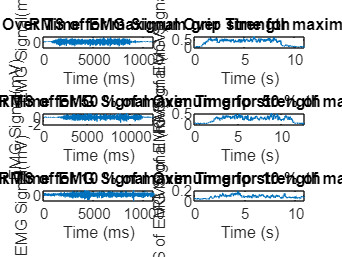

% Plot the RMS values with respect to time
figure;
subplot(3,2,1);
plot(force_max);
xlabel('Time (ms)');
ylabel('EMG Signal(mV)');
title('EMG Signal Over Time for maximum grip strength');
subplot(3,2,2);
plot(timeRMS_max, rmsValues_max);
xlabel('Time (s)');
ylabel('RMS of EMG Signal (mV)');
title('RMS of EMG Signal Over Time for maximum grip strength');
subplot(3,2,3);
plot(force_50);
xlabel('Time (ms)');
ylabel('EMG Signal(mV)');
title('EMG Signal Over Time for 50 % of maximum grip strength');
subplot(3,2,4);
plot(timeRMS_50, rmsValues_50);
xlabel('Time (s)');
ylabel('RMS of EMG Signal (mV)');
title('RMS of EMG Signal Over Time for 50 % of maximum grip strength');
subplot(3,2,5);
plot(force_10);
xlabel('Time (ms)');
ylabel('EMG Signal(mV)');
title('EMG Signal Over Time for 10 % of maximum grip strength');
subplot(3,2,6);
plot(timeRMS_10, rmsValues_10);
xlabel('Time (s)');
ylabel('RMS of EMG Signal (mV)');
title('RMS of EMG Signal Over Time for 10 % of maximum grip strength');